delay_os = 4800

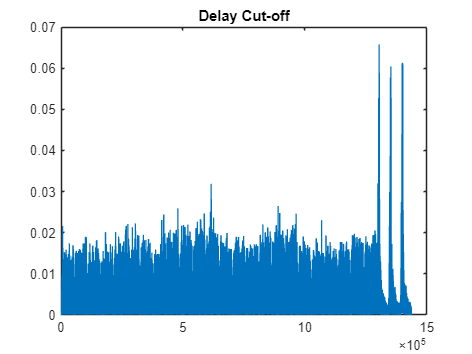

ofdm =      1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2


clear all;
load("testing_rece_data_171846_1.mat");
y_test1_in = rece_data_ofdm_test;
load("testing_rece_data_171846_2.mat");
y_test2_in = rece_data_ofdm_test;
load("testing_rece_data_171846_3.mat");
y_test3_in = rece_data_ofdm_test;
load("benchmark_rece_data_172648_1.mat");
y_bench1_in = rece_data_ofdm_bench;
load("benchmark_rece_data_172648_2.mat");
y_bench2_in = rece_data_ofdm_bench;
load("benchmark_rece_data_172648_3.mat");
y_bench3_in = rece_data_ofdm_bench;

a_est = 6.5235e-4;

zb1 = part2function(y_bench1_in, a_est);

delay_os = 4800

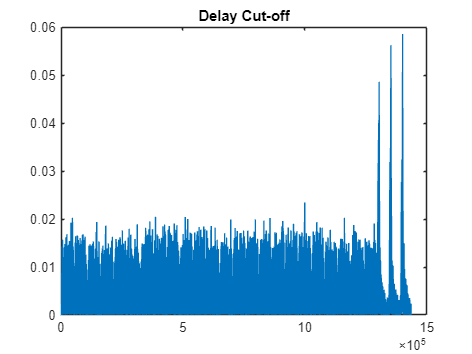

ofdm =      1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2


zb2 = part2function(y_bench2_in, a_est);

delay_os = 4800

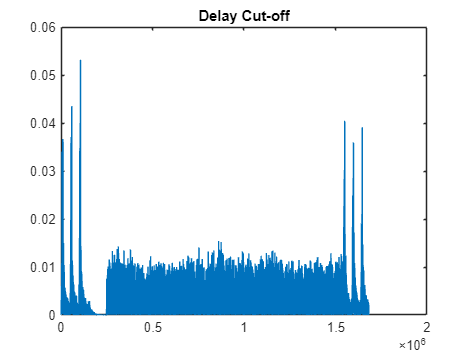

ofdm =      1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2


zb3 = part2function(y_bench3_in, a_est);

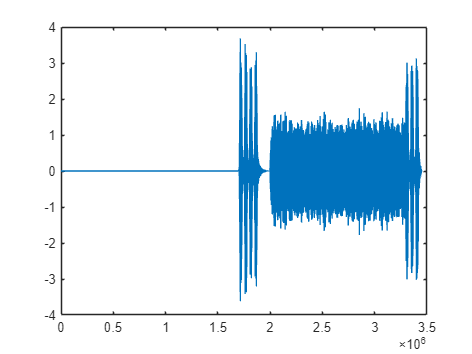

Array indices must be positive integers or logical values.

Error in part2function (line 63)
Ytilda_n0 = Ytilda_pb_re(n_0:end);    % Truncates signal to start at n_0

zt1 = part2function(y_test1_in, a_est);

zt2 = part2function(y_test2_in, a_est);
zt3 = part2function(y_test3_in, a_est);

[ber_bench1, bler_bench1, ber_bench2, bler_bench2, ber_bench3, bler_bench3] = part3function(zb1, zb2, zb3)
[ber_test1, bler_test1, ber_test2, bler_test2, ber_test3, bler_test3] = part3function(zt1, zt2, zt3)